clearvars

## Image Source Method – Room Impuls Response 

We will implement a second version of the image source method using the method described here (https://link.springer.com/content/pdf/10.1007/s11042-015-2943-4.pdf).

Instead of producing an output wave, this method returns an impuls response i.e. the rooms impuls response (RIR).

### Initial parameters

T = 20; % [°Celcius] air temperature
H = 5.2; % [g/m^3] average absolute air humidity in a room.
Lx = 5; % [m] room dimension in x direction
Ly = 5; % [m] room dimension in y direction
Lz = 5; % [m] room dimension in z direction
Fs = 44100; % [Hz] sampling frequency
Ts = 4096; % number of timesteps
f = 1:10000; % [Hz] all frequency in range
t_array = (0:Ts)*(1/Fs); % time array

The order in which the walls will be handled is given by:

North - South - West - East - Bottom - Top

Where North is located on the x-axis, West on the y-axis, Bottom on the z-axis

respectively the order of the walls absorption coefficients.

$\alpha_{x1}$ - $\alpha_{x2}$ - $\alpha_{y1}$ - $\alpha_{y2}$ - $\alpha_{z1}$ - $\alpha_{z2}$

With x pointing east - y pointing up - z point north

S = [Lx * Ly, Lx*Ly, Lz*Ly, Lz*Ly, Lz*Lx, Lz*Lx]; % Wall surfaces
abs_alpha = [0.5,0.1,0,0.5,0.1,0]; % Wall absorption coefficient
beta = sqrt(1-abs_alpha); % Wall reflection coefficient

This method consists of six steps:

### (1) Calculating the speed of sound in given environment:


$$c = 331\sqrt{1+0.0036T
$$


where 

$c$ in $\frac{m}{s^2}
$ is the speed of sound,

$T$ is the airs temperature in celcius.

c = 331*sqrt(1+0.0036*T);

### (2) Calculating the reverberation time $T_{60}(f)$

$T_{60}(f) = \frac{55.3V}{c[A_{mat}(f) + 4m_{air}(f)V]}$ is the room reverberation time

where 

$V=L_x\times Ly \times Lz$ in $m^3
$ is the rooms volume,

$L_x, L_y, L_z
$ are the rooms dimensions,

$A_{mat}(f) = \sum^6_{i=0}(1-\beta_i^2 )S_i$ is the total material absorption surface

$\beta _i(f)$ is the frequency-dependant reflection coefficient of the $i
$-th wall (1 to 6),

$S_i
$ is the wall surface,

$m_{air} (f) = 5.5 \times 10^{-4} \times \frac{50}{H}\times\bigg(\frac{f}{1000}\bigg)^{1.7}
$ in $\frac{dB}{m
}$ is an estimation of the sound intensity absorption of air

$H$ in $\frac{g}{m^3}$ is the humidity of air.

V = Lx*Ly*Lz; % [m^3] rooms volume
A_mat = @(f) sum((1-beta.^2).*S); % total material absorption surface
m_air = @(f) 5.5*10e-4*(50/H)*(f/1000).^1.7; % [db/m] sound intensity absorption of air
T_60 = @(f) (55.3*V)./(c*(A_mat(f) + m_air(f)*V)); % [s] room reverberation time

### (3) Calculating the length of the Room Impulse Response $L_{RIR}$

$L_{RIR} =f_s \max_f T_{60} (f)$ is the length of the room impulse reponse

where

$f_s
$ is the sampling frequency,

$\max_f(.)
$ is the maximum over all frequncies.

n = length(f);
T_60_mat = zeros(1,n);
for i=1:n
    T_60_mat(i) = T_60(f(i));
end
L_rir = Fs * max(T_60_mat);

### (4) Determine the number of image sources

$\hat{N}_u = \frac{c\bigg[\max_f T_{60}(f)\bigg]}{2L_u}$  with $-\hat{N}_u \leq m_u \leq \hat{N}_u$

where 

$m_u
$ is the reflection order with $u \in \{x,y,z\}
$.

$\hat{N} = 2^3 (2\hat{N}_x+1)(2\hat{N}_y +1)(2\hat{N}_z+1)$ is the number of image sources.

L_u = [Lx,Ly,Lz];
N_u = (c * (max(T_60_mat)))./(2*L_u);
N = 2^3 * (2*N_u(1)+1)*(2*N_u(2)+1)*(2*N_u(3)+1);

### (5) Calculating the propagation delay $\tau_{\tilde{s_k}s_0}
$ and the decay coefficient $\alpha_{\tilde{s_k}s_0}
$

$\tau_{\tilde{s_k}s_0} = \frac{ |\mathbf{d}_{\tilde{s_k}s_0}|}{c}
$ is the propagation delay

where

$\mathbf{d}_{\tilde{s_k}s_0} =

$$\left\lbrack \begin{array}{c}
\left(x_0 -\tilde{x_0 } +2p_x \tilde{x_0 } +\left(2m_x L_x \right)\right)\\
\left(y_0 -\tilde{y_0 } +2p_y \tilde{y_0 } +\left(2m_y L_y \right)\right)\\
\left(z_0 -\tilde{z_0 } +2p_z \tilde{z_0 } +\left(2m_z L_z \right)\right)
\end{array}\right\rbrack$ is the distance between the k-th source and the receiver

where

$R_0\{x_0,y_0,z_0\}$ is the receivers position.

$S_0\{\tilde{x_0},\tilde{y_0},\tilde{z_0}\}$ is the source position.

$m\{x,y,z\}$ and $p\{p,y,z\}$ are used to index the image sources.

All possible combinations of $m\{x,y,z\}$ and $p\{p,y,z\}$ need to be traversed to consider all sound sources.

$\alpha_{\tilde{s_k}s_0} = \frac{\beta_{\tilde{s_k}s_0}}{4\pi |\mathbf{d}_{\tilde{s_k}s_0}|$ is the decay coefficient

where

$\beta_{\tilde{s_k}s_0} = \beta_{x1}^{|m_x + p_x|}\beta_{x2}^{|m_x|}\beta_{y1}^{|m_y + p_y|}\beta_{y2}^{|m_y|}\beta_{z1}^{|m_z + p_z|}\beta_{z2}^{|m_z|}$ for the k-th image source

where 

$\beta_{x1}$ and $\beta_{x2}$ are the reflection coefficients of the walls located at $x=0$ and $x=L_x$ respectively.

#### Compute distance between receiver and all images

Lx = 4; Ly = 4; Lz = 4;
S = [2,2,2]; % (x,y,z) source position
R = [2,1,1]; % (x,y,z) receiver position
order = 3; % image order
m = [-1:1;-1:1;-1:1]; % image order vector
p = [0,1;0,1;0,1]; % is order odd
d = zeros(3,length(m(1))); % prealocate distance between k-th source and receiver
dx = (R(1)-S(1) + 2.*p(1,:)*S(1) + 2.*m(1,:)'*Lx)'; % d_x for all combinations of m and p
dy = (R(2)-S(2) + 2.*p(1,:)*S(2) + 2.*m(1,:)'*Ly)'; % analogous for d_y
dz = (R(3)-S(3) + 2.*p(1,:)*S(3) + 2.*m(1,:)'*Lz)'; % analogous for d_z
d = [cat(2,dx(1,:),dx(2,:));cat(2,dy(1,:),dy(2,:));cat(2,dz(1,:),dz(2,:))];

#### Compute reflection coefficient for all image sources

beta_mat = (beta(1).^abs(m(1,:)'+p(1,:)).*beta(2).^abs(m(1,:)').*beta(3).^abs(m(2,:)'+p(2,:)).*beta(4).^abs(m(2,:)').*beta(5).^abs(m(3,:)'+p(3,:)).*beta(6).^abs(m(3,:)'))';

Index exceeds the number of array elements (1).

beta_mat = cat(2,beta_mat(1,:),beta_mat(2,:));

#### Compute the decay coefficient

decay_alpha = beta_mat./(4*pi*vecnorm(d));

#### Compute propagation delay

theta = vecnorm(d)/c;

### (6) Calculating room impule response (RIR)


$$h(\mathbf{\tilde{s}},s_0,t) = \sum_kh(\tilde{s_k},s_0,t)=\sum_k\alpha _{\tilde{s_k}s_0}\delta (t-\tau _{\tilde{s_k}s_0})$$


where 

$\delta(.)$ is the dirac delta function.


$$\delta _{LPF}(n-\varepsilon )=$$

$$\left\lbrace \begin{array}{ll}
\frac{1}{2}\left(1+\cos \left(\frac{2\pi \left(n-\varepsilon \right)}{N_{\omega } }\right)\right)\textrm{sinc}\left(2\pi f_c^{\prime } \left(n-\varepsilon \right)\right) & -\frac{N_{\omega } }{2}<n<\frac{N_{\omega } }{2}\\
0 & \textrm{otherwise}
\end{array}\right.$$


where 


$$\varepsilon =\tau _{\tilde{s_k}s_0}f_s - floor(\tau _{\tilde{s_k}s_0}f_s)$$


$floor(.)$ means round towards minus infinity

$N_\omega$ is the width of the impulse response (typical value is 8ms)

$f_c$ is the cut-off frequency (typical calue is the Nyquist frequency)

$f'_c = \frac{f_c}{f_s}$ ist the normalised cut-off frequency

#### Compute room impulse response

delta = delta_LPF(t_array, theta', 0.008, Fs/2, Fs)

delta =     0.4875    0.4893    0.4910    0.4928    0.4946    0.4964    0.4982    0.5000    0.5018    0.5036    0.5054    0.5072    0.5090    0.5108    0.5126    0.5144    0.5162    0.5180    0.5198    0.5215    0.5233    0.5250    0.5268    0.5285    0.5302    0.5320    0.5337    0.5354    0.5371    0.5387    0.5404    0.5421    0.5437    0.5453    0.5469    0.5485    0.5501    0.5517    0.5532    0.5548    0.5563    0.5578    0.5593    0.5607    0.5622    0.5636    0.5650    0.5664    0.5677    0.5691
    0.5010    0.5013    0.5015    0.5018    0.5020    0.5022    0.5025    0.5027    0.5029    0.5032    0.5034    0.5036    0.5038    0.5041    0.5043    0.5045    0.5047    0.5050    0.5052    0.5054    0.5056    0.5058    0.5060    0.5062    0.5064    0.5066    0.5068    0.5070    0.5072    0.5074    0.5076    0.5078    0.5080    0.5081    0.5083    0.5085    0.5087    0.5088    0.5090    0.5092    0.5093    0.5095    0.5096    0.5098    0.5099    0.5101    0.5102    0.5103    0.5105 

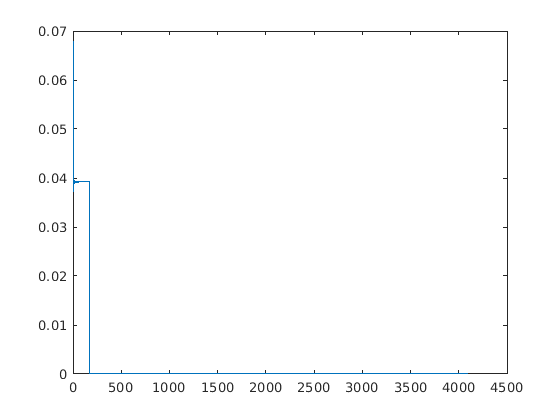

N_omega = 2*round(0.004*Fs); % 8ms
n = 0:Ts;
h = sum(decay_alpha'.*delta_LPF(n, theta', N_omega, Fs/2, Fs),1);
plot(n, h)

#### Implement delta function

function y = delta_LPF(n,theta,N_omega,fc,fs)
    % Prealocate space
    y = zeros(size(theta,1), length(n));
    epsilon = (theta.*fs)-floor(theta.*fs);
    for i=1:length(n)
        if((n(i) > (-N_omega/2)) && (n(i) < (N_omega/2)))
            y(:,i) = 0.5*(1+cos((2.*pi.*(n(i)-epsilon))./N_omega).*sinc(2.*pi.*(fc/fs).*(n(i)-epsilon)));
        else
            y(:,i) = 0;
        end
    end
    
end